# Owen Rogg Final Project 1, Battery Discharge Curve Analysis

%{
Made by Owen Rogg, April 13 2026
Project #9 in the Final Project bank
Battery Discharge Curve Analysis
Core idea is to analyze battery voltage vs time under different loads

Tasks:
Use or generate voltage-time datasets for at least two discharge tests

Normalize time axes if needed and compare discharge rates

Visualize voltage vs time(multi curve), histogram of voltage samples,
dashboard

Calculate time to threshold (e.g 3.6v), average slope in mid range

Brainstorm;
I'll find some battery discharge tests online and either directly transfer the data to this
matlab project, or manually input values that go along with the trends seen in the data.
I'll then analyze the data and perform the given tasks. Manually inputting
the data will ensure that each battery discharge dataset has the same number
of elements.

%}

%Clearing everything to get a fresh start
clear;
clc;
close all;

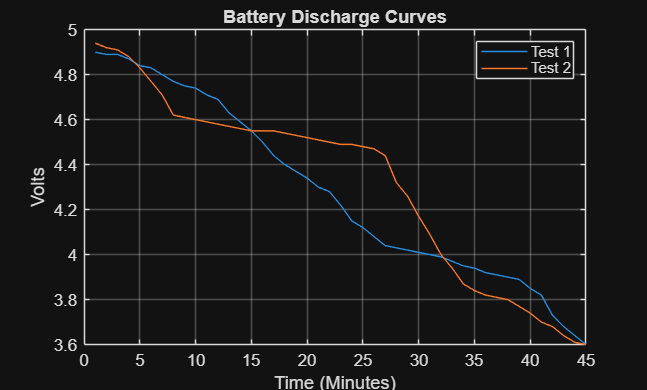

%Create two data sets and time vector
t= [1:45]';
v1=[4.90;4.89;4.89;4.87;4.84;4.83;4.80;4.77;4.75;4.74;4.71;4.69;4.63;4.59;4.55;4.50;4.44;4.40;4.37;4.34;4.30;4.28;4.22;4.15;4.12;4.08;4.04;4.03;4.02;4.01;4.00;3.99;3.97;3.95;3.94;3.92;3.91;3.90;3.89;3.85;3.82;3.73;3.68;3.64;3.60];
v2=[4.94;4.92;4.91;4.88;4.83;4.77;4.71;4.62;4.61;4.60;4.59;4.58;4.57;4.56;4.55;4.55;4.55;4.54;4.53;4.52;4.51;4.50;4.49;4.49;4.48;4.47;4.44;4.32;4.26;4.17;4.09;4.00;3.94;3.87;3.84;3.82;3.81;3.80;3.77;3.74;3.70;3.68;3.64;3.61;3.60];
%Create a plot of voltage vs time for both tests on the same graph
plot(t,v1)
hold on
plot(t,v2)
grid on
xlabel('Time (Minutes)')
ylabel('Volts')
legend('Test 1', 'Test 2');
title('Battery Discharge Curves');
hold off

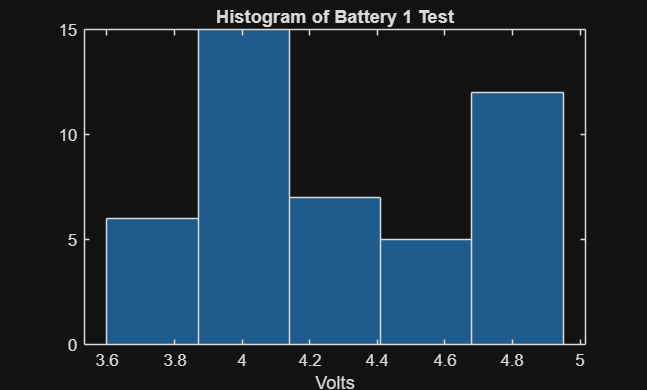

%Histogram 1
histogram(v1,5)
title('Histogram of Battery 1 Test')
xlabel('Volts')

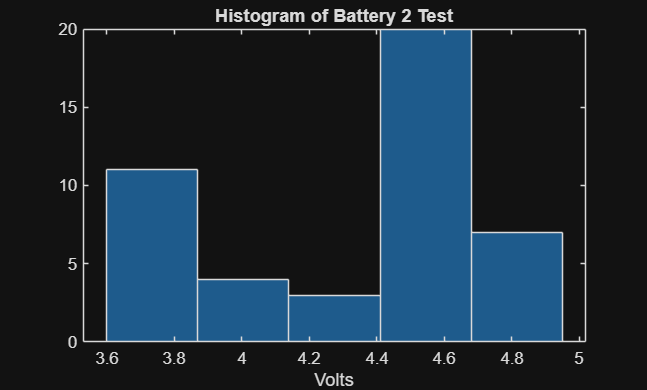

%Histogram 2
histogram(v2,5)
title('Histogram of Battery 2 Test')
xlabel('Volts')

%Table showing each batteries voltage at each time
VoltageDifference = table(t,v1,v2,'VariableNames',["Time","Voltage 1", "Voltage 2"])

VoltageDifference = 45×3 table
    Time    Voltage 1    Voltage 2
    ____    _________    _________

      1        4.9         4.94   
      2       4.89         4.92   
      3       4.89         4.91   
      4       4.87         4.88   
      5       4.84         4.83   
      6       4.83         4.77   
      7        4.8         4.71   
      8       4.77         4.62   
      9       4.75         4.61   
     10       4.74          4.6   
     11       4.71         4.59   
     12       4.69         4.58   
     13       4.63         4.57   
     14       4.59         4.56   
     15       4.55         4.55   
     16        4.5         4.55   


%Ask for voltage threshold and find time to reach each threshold
thresholdask= inputdlg('What is the voltage threshold?','Voltage Threshold');
threshold=str2num(thresholdask{1});
%Also ask user for tolerance in determining the time to reach each voltage
prompt = {sprintf('Tolerance for finding time at a voltage?\n (0.03 reccomended, lower values can \n result in inability to find a specific time, \n greater values can cause inaccuracy.)')};
toleranceask = inputdlg(prompt,'Tolerance');
tolerance = str2num(toleranceask{1});
timev1 = mean(find(abs(v1 - threshold) < (tolerance)))

timev1 = 41

timev2 = mean(find(abs(v2 - threshold) < (tolerance)))

timev2 = 37.5000

menu()